# Baja SAE Statistical Analysis

% loading results from .mat file
allResults = struct2cell(load('Results_Tables_Updated.mat'))

allResults = 39×1 cell array
    {100×17 table}
    { 75×15 table}
    {141×16 table}
    {120×17 table}
    {115×18 table}
    { 93×18 table}
    { 95×19 table}
    {120×18 table}
    {100×18 table}
    { 99×18 table}
    {100×17 table}
    { 89×18 table}
    {100×17 table}
    { 59×18 table}
    {115×18 table}
    { 79×18 table}


% example of imported data
allResults{1} 

ans = 100×17 table
    VarName1    Event                     Overall                                 SDSM2007                VarName5    VarName6    VarName7    VarName8    VarName9    VarName10    VarName11    VarName12    VarName13    VarName14    VarName15    VarName16    VarName17
    ________    _____    __________________________________________    _______________________________    ________    ________    ________    ________    ________    _________    _________    _________    ________

## Data Cleaning

% fixing results in one table
VarName17 = zeros(120, 1);
allResults{8} = [allResults{8}(:, 1:16), array2table(VarName17), allResults{8}(:, 17:18)];

### List of Events at Each Competition

% arrays for storing which events occured at which competitions
sledPull = [23 25 27 29 30 32 34 35 38 41 44 50 53 56 58];
salesPres = [22 26 28 31 36 37 40 43:60];
techEvent = [28 29 30];
techPen = [25 26 27];
techPenEnd = [22 23 24];
waterManeu = [23 27 33 35];
rockCrawl = [22 26 28 31 36 37 40 45 46 54 57]; %comes after hill climb in dataset, regular s&t comes before
mudBog = [23 29 38];

### Competition Names and Numbers

% filling row with number associated with each comp(first comp of 2000 is 1)
for i = 1:size(allResults, 1)
    allResults{i, 2} = 21 + i;
end

% array storing names of each comp
compNames = ["SDSM 2007", "UCF 2007", "RIT 2007", "Montreal 2008", "Illinois 2008", "Tennessee 2008", "Oregon 2009", "Wisconsin 2009",  "Alabama 2009", "Washington 2010", "Carolina 2010", "Rochester 2010", "Kansas 2011", "Birmingham 2011", "Illinois 2011", "Oregon 2012", "Wisconsin 2012", "Auburn 2012", "Washington 2013", "Tennessee 2013", "Rochester 2013", "UTEP 2014", "Kansas 2014","Illinois 2014", "Oregon 2015", "Auburn 2015", "Maryland 2015", "California 2016", "Tennessee 2016", "Rochester 2016", "California 2017", "Kansas 2017", "Illinois 2017", "Maryland 2018", "Kansas 2018", "Oregon 2018", "Tennessee 2019", "California 2019", "Rochester 2019"]

compNames = 1×39 string array
    "SDSM 2007"    "UCF 2007"    "RIT 2007"    "Montreal 2008"    "Illinois 2008"    "Tennessee 2008"    "Oregon 2009"    "Wisconsin 2009"    "Alabama 2009"    "Washington 2010"    "Carolina 2010"    "Rochester 2010"    "Kansas 2011"    "Birmingham 2011"    "Illinois 2011"    "Oregon 2012"    "Wisconsin 2012"    "Auburn 2012"    "Washington 2013"    "Tennessee 2013"    "Rochester 2013"    "UTEP 2014"    "Kansas 2014"    "Illinois 2014"    "Oregon 2015"    "Auburn 2015"    "Maryland 2015"    "California 2016"    "Tennessee 2016"    "Rochester 2016"    "California 2017"    "Kansas 2017"    "Illinois 2017"    "Maryland 2018"    "Kansas 2018"    "Oregon 2018"    "Tennessee 2019"    "California 2019"    "Rochester 2019"



% adding competition names to cell array
for i = 1:size(compNames, 2)
    allResults{i, 3} = compNames(i);
end

### Naming Event Columns

%for loops for naming columns. fills based on how SAE seems to fill the
%tables. competition 23 doesn't follow the pattern though
for i = 1:size(allResults, 1)
    if allResults{i, 2} ~= 23
        offset = 0;
        
        allResults{i, 1}.Properties.VariableNames([1:9]) = {'overallRank' 'carNumber' 'universityName' 'teamName' 'overallScore' 'overallDynamic' 'overallStatic' 'costScore' 'designScore'};
        
        if ismember(allResults{i, 2}, salesPres)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'salesScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, techPen)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'techPenalty'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, techEvent)
            allResults{i, 1}.Properties.VariableNames(10 + offset) = {'techScore'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames([10 + offset, 11 + offset]) = {'accelScore', 'landManeuScore'};
        
        if ismember(allResults{i, 2}, mudBog)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'mudBogScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, rockCrawl)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'rockCrawlScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, sledPull)
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'sledPullScore'};
        else
            allResults{i, 1}.Properties.VariableNames(12 + offset) = {'hillClimbScore'};
        end
        
        if ~ismember(allResults{i, 2}, rockCrawl)
            allResults{i, 1}.Properties.VariableNames(13 + offset) = {'susTracScore'};
            offset = offset + 1;
        end
        
        if ismember(allResults{i, 2}, waterManeu)
            allResults{i, 1}.Properties.VariableNames(13 + offset) = {'waterManeuScore'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames(13 + offset) = {'enduroScore'};
        
        if ismember(allResults{i, 2}, techPenEnd)
            allResults{i, 1}.Properties.VariableNames(14 + offset) = {'techPenalty'};
            offset = offset + 1;
        end
        
        allResults{i, 1}.Properties.VariableNames(14 + offset) = {'penalty'};
        
        if ~ismember(allResults{i, 2}, techPen) && ~ismember(allResults{i, 2}, techPenEnd)
            allResults{i, 1}.Properties.VariableNames(15 + offset) = {'registered'};
            allResults{i, 1}.Properties.VariableNames(16 + offset) = {'techPassed'};
        elseif ismember(allResults{i, 2}, techPen)
             allResults{i, 1}.Properties.VariableNames(15 + offset) = {'registered'};
        end
    else
        allResults{i, 1}.Properties.VariableNames = {'overallRank' 'carNumber' 'universityName' 'teamName' 'overallScore' 'designScore' 'costScore' 'accelScore' 'mudBogScore' 'susTracScore' 'waterManeuScore' 'sledPullScore' 'enduroScore' 'techPenalty' 'penalty'};
    end
    
      allResults{i, 1}.universityName = convertCharsToStrings(allResults{i, 1}.universityName);
end

allResults{1}

ans = 100×17 table
    overallRank    carNumber                  universityName                             teamName                overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    accelScore    landManeuScore    rockCrawlScore    hillClimbScore    enduroScore    techPenalty    penalty
    ___________    _________    __________________________________________    _______________________________    ____________    ______________    _____________    _________    ___________    __________    

### Cleaning University Names Data

% Paired list of names that refer to same uni

wrongNames = ["Christian Brothers College" "Arizona State Univ - Polytechnic" "California Polytechnic State Univ-SLO" "City College of the City Univ of NY"; 
              "Christian Brothers Univ" "Arizona State Univ Polytechnic" "California State Poly Univ-San Luis Obis" "City College of New York"];

% List of all universities that have participated in Baja SAE competitions

allUnis = getParticipatingUnis(allResults, wrongNames);

## Using the Database

% Get results from any competition
getCompResults(allResults, 28)

ans = 95×19 table
    overallRank    carNumber                universityName                         teamName            overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    techScore    accelScore    landManeuScore    rockCrawlScore    hillClimbScore    enduroScore    penalty    registered     techPassed
    ___________    _________    _______________________________________    ________________________    ____________    ______________    _____________    _________    ___________

% tells us which competition we're looking at
compNames(28)

ans = "California 2016"

% Find all comps a team attended with their results

warning('off') % function does some sketchy stuff with tables
tempResults = getCompsAttended(allResults, wrongNames, "Univ of Illinois - Urbana Champaign", allUnis)

tempResults = 30×26 table
        compName         overallRank    carNumber               universityName                     teamName         overallScore    overallDynamic    overallStatic    costScore    designScore    salesScore    techScore    accelScore    landManeuScore    rockCrawlScore    mudBogScore    hillClimbScore    sledPullScore    susTracScore    waterManeuScore    enduroScore    techPenalty    penalty    registered    techPassed    PassedTechOnTime
    _________________    ___________    _______

% write team results to table

writetable(tempResults, 'Output Tables\UIUCAllResults.xlsx')

% Grab Iron Team Award results for a given season 

wrongNamesTwo = strings; % university name replacement doesn't quite work yet
getIronTeamResults(allResults, wrongNamesTwo, "2019")

ans = 20×2 cell array
    {'Univ of Michigan - Ann Arbor'       }    {'2819.09'}
    {'Ecole de Technologie Superieure'    }    {'2618.96'}
    {'Rochester Institute of Technology'  }    {'2471.58'}
    {'Cornell Univ'                       }    {'2443.57'}
    {'San Diego State Univ'               }    {'2419.61'}
    {'Univ of Akron'                      }    {'2395.99'}
    {'Univ of Maryland - Baltimore County'}    {'2337.35'}
    {'Johns Hopkins Univ'                 }    {'2009.67'}
    {'Case Western Reserve Univ'          }    {'2006.46'}
    {'Univ of Nebraska - Lincoln'         }    {'1978.42'}
    {'Univ of Nevada - Las Vegas'         }    {'1972.71'}
    {'Clarkson University'                }    {'1809.46'}
    {'Univ of Illinois - Urbana Champaign'}    {'1728.32'}
    {'Iowa State Univ'                    }    {'1714.48'}
    {'New Jersey Institute of Technology' }    {'1588.22'}
    {'Queen's Univ'                       }    {'1531.26'}
    {'Virginia Tech'              

% Ranks teams by highest average score for a given season

getAvgSeasonResults(allResults, wrongNamesTwo, "2017")

ans = 224×2 cell array
    {'West Virginia Univ'                   }    {'NaN'     }
    {'Univ of Michigan - Ann Arbor'         }    {'879.6167'}
    {'Oregon State Univ'                    }    {'823.885' }
    {'Ecole De Technologie Superieure'      }    {'803.13'  }
    {'Univ of Wisconsin - Madison'          }    {'774.05'  }
    {'Rochester Institute of Technology'    }    {'749.27'  }
    {'Northeastern Univ'                    }    {'745.615' }
    {'Cornell Univ'                         }    {'739.46'  }
    {'Univ of Akron'                        }    {'737'     }
    {'Universidad De La Salle Bajio'        }    {'731.74'  }
    {'New Jersey Institute of Technology'   }    {'714.23'  }
    {'Queen's Univ - Ontario Canada'        }    {'705.1067'}
    {'Georgia Southern Univ'                }    {'703.51'  }
    {'Brigham Young Univ'                   }    {'703.22'  }
    {'Government College of Engrg Pune'     }    {'702.73'  }
    {'California Polytechnic State Univ-SLO'}  

% Ranks teams by average results across multiple seasons, with min
% competition threshold

getAvgResults(allResults, wrongNamesTwo, ["2017" "2018" "2019"], 5)

ans = 54×3 cell array
    {'Univ of Michigan - Ann Arbor'         }    {'887.0133'}    {[9]}
    {'Ecole De Technologie Superieure'      }    {'833.2633'}    {[9]}
    {'Cornell Univ'                         }    {'830.2662'}    {[8]}
    {'Rochester Institute of Technology'    }    {'826.7789'}    {[9]}
    {'Oregon State Univ'                    }    {'816.62'  }    {[5]}
    {'Univ of Akron'                        }    {'789.7544'}    {[9]}
    {'San Diego State Univ'                 }    {'759.6189'}    {[9]}
    {'California Polytechnic State Univ-SLO'}    {'724.5717'}    {[6]}
    {'Univ of Maryland - Baltimore County'  }    {'712.6037'}    {[8]}
    {'Northeastern Univ'                    }    {'682.2757'}    {[7]}
    {'Pennsylvania College of Technology'   }    {'673.815' }    {[6]}
    {'Case Western Reserve Univ'            }    {'670.6662'}    {[8]}
    {'Univ of Nebraska - Lincoln'           }    {'666.85'  }    {[9]}
    {'Université Laval'                     }    {'653.

% Average results again, but this time recording average place

getAvgPlace(allResults, wrongNamesTwo, ["2010" "2011" "2012" "2013" "2014" "2015" "2016" "2017" "2018" "2019"], 10)

ans = 120×3 cell array
    {'Oregon State Univ'                  }    {'4.2353' }    {[17]}
    {'Cornell Univ'                       }    {'4.84'   }    {[25]}
    {'Rochester Institute of Technology'  }    {'6.2'    }    {[30]}
    {'Ecole De Technologie Superieure'    }    {'6.6333' }    {[30]}
    {'Universite Laval'                   }    {'10'     }    {[13]}
    {'Univ of Maryland - Baltimore County'}    {'16.2759'}    {[29]}
    {'San Diego State Univ'               }    {'17.7222'}    {[18]}
    {'Univ of Wisconsin - Madison'        }    {'17.8824'}    {[17]}
    {'Universidad De La Salle Bajio'      }    {'18'     }    {[10]}
    {'Northeastern Univ'                  }    {'18.1304'}    {[23]}
    {'Ohio Northern Univ'                 }    {'19.48'  }    {[25]}
    {'Univ of Nebraska - Lincoln'         }    {'20.7083'}    {[24]}
    {'Pennsylvania College of Technology' }    {'21.0714'}    {[14]}
    {'McGill Univ'                        }    {'21.2'   }    {[20]}
    {'Georg

% Find the closest competitions ever

getClosestComps(allResults)

ans = 10×4 cell array
    {["Maryland 2018"  ]}    {["Rochester Institute of Technology"]}    {[931.9100]}    {[8.2626e-04]}
    {["Carolina 2010"  ]}    {["Universite Laval"                 ]}    {[911.9000]}    {[    0.0013]}
    {["Tennessee 2013" ]}    {["Cornell Univ"                     ]}    {[845.6200]}    {[    0.0027]}
    {["Tennessee 2008" ]}    {["Queen's Univ - Ontario Canada"    ]}    {[855.7700]}    {[    0.0049]}
    {["Wisconsin 2009" ]}    {["Oregon State Univ"                ]}    {[942.9200]}    {[    0.0061]}
    {["SDSM 2007"      ]}    {[" Auburn University"               ]}    {[855.2800]}    {[    0.0083]}
    {["Illinois 2017"  ]}    {["Ecole De Technologie Superieure"  ]}    {[886.7700]}    {[    0.0112]}
    {["Kansas 2014"    ]}    {["Centro Universitario Da FEI"      ]}    {[885.6800]}    {[    0.0117]}
    {["Illinois 2014"  ]}    {["Cornell Univ"                     ]}    {[930.0300]}    {[    0.0128]}
    {["California 2017"]}    {["Ecole De Technologi

### Flexible Result Correlation

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat       pValue  
                   ________    _______    ______    __________

    (Intercept)     25.731      5.5434    4.6417    1.6587e-05
    x1             0.48451     0.12779    3.7916    0.00032355


Number of observations: 69, Error degrees of freedom: 67
Root Mean Squared Error: 17.2
R-squared: 0.177,  Adjusted R-Squared: 0.164
F-statistic vs. constant model: 14.4, p-value = 0.000324

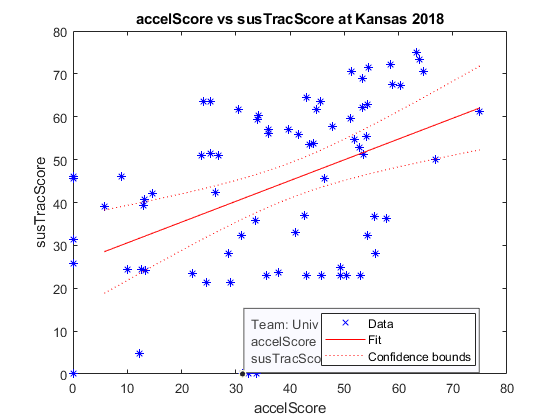

% Graphs results from any competition against eachother

graphResults2D(allResults, 56, "accelScore", "susTracScore");

### 3D Correlation

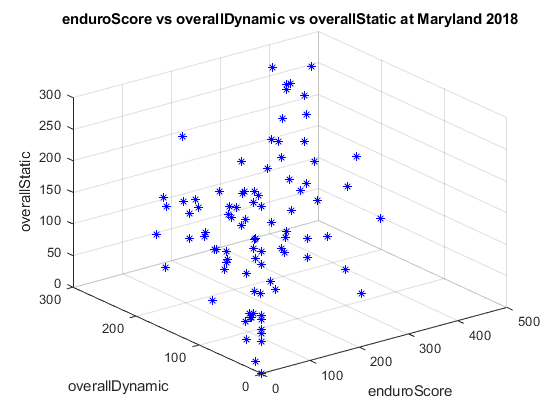


% Graph 3 sets of scores together

graphResults3D(allResults, 55, "enduroScore", "overallDynamic", "overallStatic");

## Calculating Correlation of Results

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      25.806      4.0368    6.3927    1.3622e-08
    x1             0.047075    0.008319    5.6588    2.8115e-07


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 14.2
R-squared: 0.305,  Adjusted R-Squared: 0.295
F-statistic vs. constant model: 32, p-value = 2.81e-07

fit_line = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE       tStat       pValue  
                   ________    ________    ______    __________

    (Intercept)      25.806      4.0368    6.3927    1.3622e-08
    x1             0.047075    0.008319    5.6588    2.8115e-07


Number of observations: 75, Error degrees of freedom: 73
Root Mean Squared Error: 14.2
R-squared: 0.305,  Adjusted R-Squared: 0.295
F-statistic vs. constant model: 32, p-value = 2.81e-07

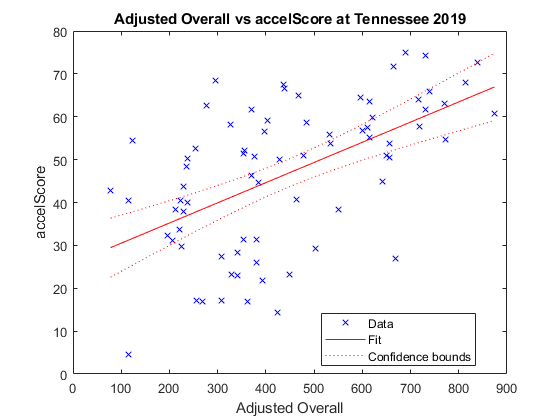

temp = findResultCorrelation(allResults, 58, "accelScore");